## **Session 2**

# **Descriptive statistics and Outliers detection in MATLAB**

## **Data Preprocessing & Quality Control for Neural Signals **

- **Why is it Essential?**:

- Raw neural signals are inherently noisy (biological, environmental).

- Specific analyses (e.g., ERP averaging, time-frequency) require clean, segmented data.

- Poor preprocessing can lead to spurious results and misinterpretations.

- **Goals of Preprocessing**:

- Remove unwanted noise and artifacts

- Isolate relevant brain activity.

- Prepare data for downstream statistical analyses.

- **Impact of Poor Preprocessing**:

- Reduced signal-to-noise ratio.

- Distorted waveforms or oscillatory patterns.

- Increased variability, leading to reduced statistical power.

- False positives or negatives in hypothesis testing.

% --- EEGLAB Preprocessing for Cohen & Ridderinkhof Data ---

% This script assumes EEGLAB is in your MATLAB path and the .mat file 
% already contains a variable named 'EEG' that is a proper EEGLAB structure.
clear;
clc;
warning('off', 'all');
%restoredefaultpath
%addpath('C:\matlab_path\eeglab2025.0.0');
eeglab('nogui');

eeglab: options file is C:\Users\abolfazl\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "EEG-BIDS" v? (see >> help eegplugin_eegbids) - new version 10.4 available
EEGLAB: adding "ICLabel" v? (see >> help eegplugin_iclabel) - new version 1.7 available (critical bug fix)
EEGLAB: adding "clean_rawdata" v? (see >> help eegplugin_clean_rawdata) - new version 2.11 available
EEGLAB: adding "dipfit" v? (see >> help eegplugin_dipfit) - new version 5.6 available
EEGLAB: adding "firfilt" v? (see >> help eegplugin_firfilt) - new version 2.8 available



% Load the data from the .mat file. It's already an EEGLAB struct.
load('sampleEEGdata.mat');

% 1. Data Setup & Event Selection
% We will isolate trials for the "Congruent" condition.
% From the event table, event code '1' represents a congruent stimulus.
congruent_event_code = 1;

% Use pop_selectevent to create a new EEG dataset containing ONLY congruent trials.
EEG_congruent = pop_selectevent(EEG, 'type', congruent_event_code, 'deleteevents', 'on');

% Now, get the raw data for the Cz channel from this new, selected dataset.
cz_channel_index = 48;
cz_data_raw = squeeze(EEG_congruent.data(cz_channel_index, :, :));

% Calculate the mean ERP of the RAW, unfiltered data for the congruent condition.
mean_erp_raw = mean(cz_data_raw, 2);

% Choose a single trial to plot for comparison (e.g., the first trial).
single_trial_raw = cz_data_raw(:, 1);

% 2. Preprocessing Step: Filtering
% We'll filter this new, congruent-only dataset.
EEG_congruent_filtered = EEG_congruent;

% Apply high-pass filter (0.5 Hz) to remove slow drifts.
fprintf('\nApplying high-pass filter (0.5 Hz) to Congruent condition...\n');


Applying high-pass filter (0.5 Hz) to Congruent condition...


EEG_congruent_filtered = pop_eegfiltnew(EEG_congruent_filtered, 'locutoff', 0.5);

pop_eegfiltnew() - performing 1691 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.499881656804734 Hz
pop_eegfiltnew() - passband edge(s): 0.5 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.250059171597633 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00



% Apply low-pass filter (30 Hz) to remove high-frequency noise.
fprintf('Applying low-pass filter (30 Hz) to Congruent condition...\n');

Applying low-pass filter (30 Hz) to Congruent condition...


EEG_congruent_filtered = pop_eegfiltnew(EEG_congruent_filtered, 'hicutoff', 30);

pop_eegfiltnew() - performing 115 point lowpass filtering.
pop_eegfiltnew() - transition band width: 7.41052631578947 Hz
pop_eegfiltnew() - passband edge(s): 30 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 33.7052631578947 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


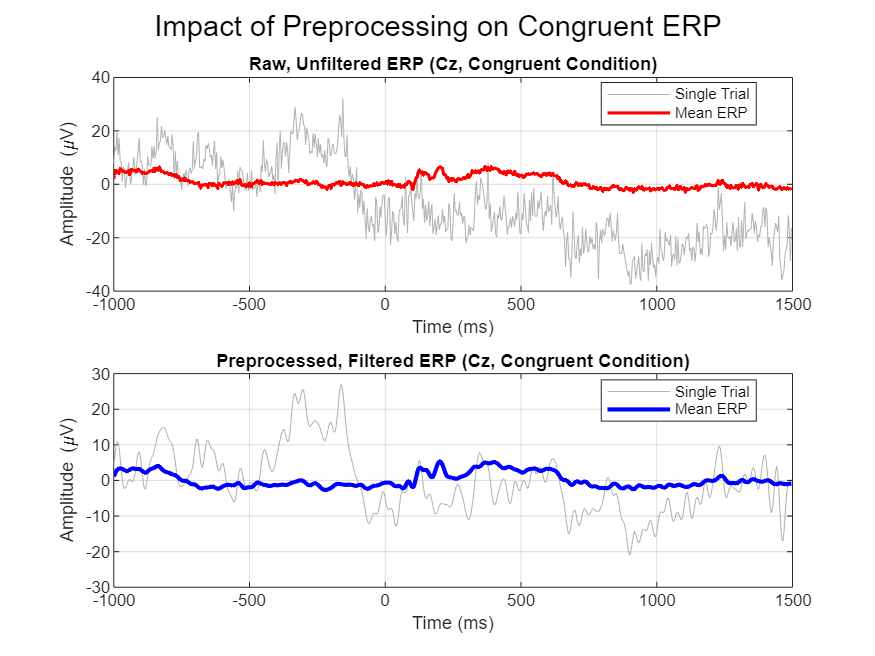


% 3. Extract and average the filtered data
cz_data_filtered = squeeze(EEG_congruent_filtered.data(cz_channel_index, :, :));
mean_erp_filtered = mean(cz_data_filtered, 2);

% Get the same single trial, but now filtered.
single_trial_filtered = cz_data_filtered(:, 1);

% 4. Create a comparison plot with two subplots
figure('Name', 'Raw vs. Filtered ERP for Congruent Trials');

% Subplot 1: Raw, Unfiltered ERP for Congruent Condition
subplot(2, 1, 1);
plot(EEG_congruent.times, single_trial_raw, 'Color', [0.7 0.7 0.7], 'LineWidth', 0.5);
hold on;
plot(EEG_congruent.times, mean_erp_raw, 'r', 'LineWidth', 1.5);
title('Raw, Unfiltered ERP (Cz, Congruent Condition)');
xlabel('Time (ms)');
ylabel('Amplitude (\muV)');
grid on;
legend('Single Trial', 'Mean ERP', 'Location', 'best');
hold off;

% Subplot 2: Filtered ERP for Congruent Condition
subplot(2, 1, 2);
plot(EEG_congruent_filtered.times, single_trial_filtered, 'Color', [0.7 0.7 0.7], 'LineWidth', 0.5);
hold on;
plot(EEG_congruent_filtered.times, mean_erp_filtered, 'b', 'LineWidth', 2);
title('Preprocessed, Filtered ERP (Cz, Congruent Condition)');
xlabel('Time (ms)');
ylabel('Amplitude (\muV)');
grid on;
legend('Single Trial', 'Mean ERP', 'Location', 'best');
hold off;

sgtitle('Impact of Preprocessing on Congruent ERP');

## **Signal-to-Noise Ratio (SNR)**

**SNR** is a measure of the quality of a signal. It's the ratio of the power of the signal you want to measure (the ERP) to the power of all the unwanted stuff (the noise). A high SNR means your signal is strong and clear relative to the background noise.

In EEG, the "signal" is the consistent brain response to a specific event (like the N200 component in the congruent trials). The "noise" is everything else: unrelated brain activity, muscle movements, eye blinks, and electrical interference.


$$$$SNR = \frac{\sigma_{\text{signal}}^2}{\sigma_{\text{noise}}^2}$$$$


**How Preprocessing Improves SNR with this Data:**

- **Raw Data**: When you look at the raw, unfiltered single trial in the first subplot, you see a jagged, chaotic line.  The noise (high-frequency spikes and slow drifts) has a very high power, which makes the SNR very low. The underlying ERP signal is present but buried.

- **Filtered Data**: The filtering steps (`pop_eegfiltnew`) reduce the power of the noise by removing unwanted frequencies. This makes the signal smoother and cleaner.  By removing this noise, we increase the ratio in the equation, thus **increasing the SNR**.

**Statistical power** is the probability of a statistical test correctly detecting an effect when one truly exists. In simpler terms, it's your ability to find a real difference if there is one. In other words, it's the likelihood of avoiding a **Type II error** (a "false negative").

A common statistical test for comparing ERPs (e.g., between congruent and incongruent conditions) is a t-test. The formula for a t-statistic looks something like this:


$$$$t = \frac{\bar{X}_1 - \bar{X}_2}{s_{\bar{X}_1 - \bar{X}_2}}$$$$


The **standard error** is directly tied to the variability (noise) in your data. High noise leads to high variability and a large standard error.

% --- T-Test Comparison: Raw vs. Filtered Data ---
% This script loads EEG data, separates it into two conditions.
% to demonstrate the impact of preprocessing on statistical power.

% IMPORTANT: Ensure EEGLAB is installed and added to your MATLAB path.
% Run 'eeglab' in the command window once to initialize.



% Define event codes and channel for comparison.
congruent_event_code = 1;
incongruent_event_code = 2;
cz_channel_index = 48;

fprintf('--- Starting T-Test Analysis on Filtered Data ---\n');

--- Starting T-Test Analysis on Filtered Data ---



% --- 1. Isolate Raw Data for Both Conditions ---
% We first separate the raw data into our two conditions of interest.

fprintf('Separating trials for Congruent and Incongruent conditions...\n');

Separating trials for Congruent and Incongruent conditions...


EEG_congruent_raw = pop_selectevent(EEG, 'type', congruent_event_code, 'deleteevents', 'on');
EEG_incongruent_raw = pop_selectevent(EEG, 'type', incongruent_event_code, 'deleteevents', 'on');

Removing 61 trial(s)...
eeg_checkset warning: 1/38 events had out-of-bounds latencies and were removed




% --- 2. Preprocess the Data (Filtering) ---
% We now create filtered versions of the datasets to ensure high SNR for reliable statistical testing.
fprintf('\nFiltering both Congruent and Incongruent datasets (creating High SNR version)...\n');


Filtering both Congruent and Incongruent datasets (creating High SNR version)...


EEG_congruent_filtered = pop_eegfiltnew(EEG_congruent_raw, 'locutoff', 0.5, 'hicutoff', 30);

pop_eegfiltnew() - performing 1691 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.499881656804734 Hz
pop_eegfiltnew() - passband edge(s): [0.5 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.250059171597633 30.2499408284024] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EEG_incongruent_filtered = pop_eegfiltnew(EEG_incongruent_raw, 'locutoff', 0.5, 'hicutoff', 30);

pop_eegfiltnew() - performing 1691 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.499881656804734 Hz
pop_eegfiltnew() - passband edge(s): [0.5 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.250059171597633 30.2499408284024] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00




% --- 3. Extract Amplitudes from FILTERED Data and Identify Peak Time ---
% We'll find the peak of the N200 in the filtered congruent data and perform the t-test there.
cz_congruent_filtered_data = squeeze(EEG_congruent_filtered.data(cz_channel_index, :, :));
cz_incongruent_filtered_data = squeeze(EEG_incongruent_filtered.data(cz_channel_index, :, :));
mean_erp_congruent_filtered = mean(cz_congruent_filtered_data, 2);

% Find N200 peak index for the filtered data.
[~, start_idx] = min(abs(EEG_congruent_filtered.times - 200));
[~, end_idx] = min(abs(EEG_congruent_filtered.times - 400));
[~, relative_peak_idx] = min(mean_erp_congruent_filtered(start_idx:end_idx));
peak_time_idx = start_idx + relative_peak_idx - 1;
peak_time_ms = EEG_congruent_filtered.times(peak_time_idx);

fprintf('\nIdentified N200 peak in FILTERED Congruent ERP at %.2f ms.\n', peak_time_ms);


Identified N200 peak in FILTERED Congruent ERP at 261.72 ms.



% Extract amplitudes at the peak time for the filtered data.
amplitudes_congruent_filtered = cz_congruent_filtered_data(peak_time_idx, :)';
amplitudes_incongruent_filtered = cz_incongruent_filtered_data(peak_time_idx, :)';

% --- 4. Perform the T-Test on FILTERED Data ---
% Perform the t-test on the filtered data (High SNR).
[h_filtered, p_filtered, ~, stats_filtered] = ttest2(amplitudes_congruent_filtered, amplitudes_incongruent_filtered);
fprintf('\n--- T-Test on FILTERED Data (High SNR) at %.2f ms ---\n', peak_time_ms);


--- T-Test on FILTERED Data (High SNR) at 261.72 ms ---


fprintf('  T-statistic: %.2f, P-value: %.4f\n', stats_filtered.tstat, p_filtered);

  T-statistic: -0.13, P-value: 0.8997


if h_filtered
    fprintf('  Result: Statistically significant (p < 0.05). \x2705\n');
else
    fprintf('  Result: NOT statistically significant (p > 0.05). \x274C\n');
end

  Result: NOT statistically significant (p > 0.05). ❌


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


## **Descriptive Statistics in Data Quality Control**

**Measures of Central Tendency**

**Mean (****x****ˉ**** or ****μ****)**

The **arithmetic average** of a dataset. It's sensitive to outliers.


$$$$\bar{x} = \frac{1}{n}\sum_{i=1}^{n} x_i$$$$


Where:

- n is the number of data points.

- xi represents each individual data point.

**Median**

The **middle value** when a dataset is ordered from least to greatest. If there's an even number of data points, it's the average of the two middle values. It's robust to outliers.

**Mode**

The **most frequent value** in a dataset. A dataset can have one mode (unimodal), multiple modes (multimodal), or no mode.

**Measures of Dispersion**

**Variance (σ****2**** or ****s****2****)**

The **average of the squared differences from the mean**. It quantifies how spread out the data points are.

For a **population variance** (σ2):


$$$$\sigma^2 = \frac{1}{N}\sum_{i=1}^{N} (x_i - \mu)^2$$$$


For a **sample variance** (s2):


$$$$s^2 = \frac{1}{n-1}\sum_{i=1}^{n} (x_i - \bar{x})^2$$$$


Where:

- N is the population size; n is the sample size.

- μ is the population mean; xˉ is the sample mean.

**Standard Deviation (****σ**** or ****s****)**

The **square root of the variance**. It represents the typical distance of data points from the mean and is in the same units as the data.

For a **population standard deviation** (σ):


$$$$\sigma = \sqrt{\frac{1}{N}\sum_{i=1}^{N} (x_i - \mu)^2}$$$$


For a **sample standard deviation** (s):


$$$$s = \sqrt{\frac{1}{n-1}\sum_{i=1}^{n} (x_i - \bar{x})^2}$$$$


**Range**

The difference between the **maximum and minimum values** in a dataset. 

Range=xmax−xmin

**Interquartile Range (IQR)**

The difference between the **third quartile (Q3)** and the **first quartile (Q1)**. It represents the range of the middle 50% of the data and is robust to outliers.

IQR=Q3−Q1

Where:

- Q1 is the 25th percentile of the data.

- Q3 is the 75th percentile of the data.

**Data Distribution**

**Histograms**

A graphical representation of the distribution of numerical data. It uses bars to show the frequency of data points within specified intervals (bins).

**Skewness**

A measure of the **asymmetry of the probability distribution** of a real-valued random variable about its mean.

- **Positive Skew (Right-skewed)**: The tail is longer on the right side of the distribution, and the mass of the distribution is concentrated on the left. Mean > Median > Mode.

- **Negative Skew (Left-skewed)**: The tail is longer on the left side of the distribution, and the mass of the distribution is concentrated on the right. Mean < Median < Mode.

The formula for **sample skewness** (g1):


$$$$g_1 = \frac{n}{(n-1)(n-2)} \sum_{i=1}^{n} \left(\frac{x_i - \bar{x}}{s}\right)^3$$$$


**Kurtosis**

A measure of the "tailedness" of the probability distribution of a real-valued random variable. It describes the shape of the distribution's tails relative to the tails of a normal distribution.

- **Leptokurtic (Positive Kurtosis)**: Has heavier tails and a sharper peak than a normal distribution.

- **Platykurtic (Negative Kurtosis)**: Has lighter tails and a flatter peak than a normal distribution.

- **Mesokurtic (Kurtosis of 0 for excess kurtosis)**: Similar to a normal distribution.

The formula for **sample kurtosis** (g2):


$$$$g_2 = \frac{n(n+1)}{(n-1)(n-2)(n-3)} \sum_{i=1}^{n} \left(\frac{x_i - \bar{x}}{s}\right)^4 - \frac{3(n-1)^2}{(n-2)(n-3)}$$$$


% --- Descriptive Statistics on Cohen & Ridderinkhof Data (Fixed Microvolt Symbol) ---

% IMPORTANT: Ensure EEGLAB is installed and added to your MATLAB path.
% Run 'eeglab' in the command window once to initialize.

% Load the EEG data.
load('sampleEEGdata.mat');

% Define event code and channel for analysis.
congruent_event_code = 1;
cz_channel_index = 48; % Cz channel is commonly the 48th electrode

fprintf('--- Computing Descriptive Statistics for Congruent ERP (Cz) ---\n');

--- Computing Descriptive Statistics for Congruent ERP (Cz) ---



% --- 1. Separate Trials for Congruent Condition ---
fprintf('Separating trials for Congruent condition (event code %d)...\n', congruent_event_code);

Separating trials for Congruent condition (event code 1)...


EEG_congruent = pop_selectevent(EEG, 'type', congruent_event_code, 'deleteevents', 'on');

% --- 2. Preprocessing: Filter Data ---
fprintf('Applying high-pass (0.5 Hz) and low-pass (30 Hz) filters...\n');

Applying high-pass (0.5 Hz) and low-pass (30 Hz) filters...


EEG_congruent = pop_eegfiltnew(EEG_congruent, 'locutoff', 0.5, 'hicutoff', 30);

pop_eegfiltnew() - performing 1691 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.499881656804734 Hz
pop_eegfiltnew() - passband edge(s): [0.5 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.250059171597633 30.2499408284024] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00



% --- 3. Extract Amplitudes at a Specific Time Point ---
% We'll analyze the amplitude distribution at the N200 peak.
% First, get the Cz channel data and its mean ERP.
cz_congruent_data = squeeze(EEG_congruent.data(cz_channel_index, :, :));
mean_erp_congruent = mean(cz_congruent_data, 2);

% Define a time window for the N200 peak (e.g., 200-400 ms post-stimulus).
time_window_start = 200; % ms
time_window_end = 400;   % ms

% Convert time window to indices.
[~, start_idx] = min(abs(EEG_congruent.times - time_window_start));
[~, end_idx] = min(abs(EEG_congruent.times - time_window_end));

% Find the most negative peak (N200-like) within this window.
[~, relative_peak_idx] = min(mean_erp_congruent(start_idx:end_idx));
peak_time_idx = start_idx + relative_peak_idx - 1; % Absolute index of the peak
peak_time_ms = EEG_congruent.times(peak_time_idx);

fprintf('\nAnalyzing ERP amplitudes at the identified N200 peak (%.2f ms) across trials.\n', peak_time_ms);


Analyzing ERP amplitudes at the identified N200 peak (261.72 ms) across trials.



% Extract the amplitude values from each trial at this specific peak time.
amplitudes_at_peak = cz_congruent_data(peak_time_idx, :);

fprintf('\n--- Measures of Central Tendency ---\n');


--- Measures of Central Tendency ---


% Mean: Arithmetic average. Sensitive to outliers.
erp_mean = mean(amplitudes_at_peak);
fprintf('Mean ERP Amplitude: %.2f uV\n', erp_mean); % Changed \u00B5V to uV for fprintf

Mean ERP Amplitude: 0.61 uV


% What it gives: The typical or average amplitude value at this specific time point across all congruent trials.
% What it doesn't give: Information about the spread of data or the presence of extreme values.

% Median: Middle value when data is ordered. Robust to outliers.
erp_median = median(amplitudes_at_peak);
fprintf('Median ERP Amplitude: %.2f uV\n', erp_median); % Changed \u00B5V to uV for fprintf

Median ERP Amplitude: 0.02 uV


% What it gives: The central value that splits the data into two equal halves. Less affected by extreme noisy trials or outliers.
% What it doesn't give: The actual frequency of values or the arithmetic average.

% Mode: Most frequent value. Useful for categorical data.
[counts, bins] = hist(amplitudes_at_peak, 50); % Binning to find a meaningful mode
[~, max_count_idx] = max(counts);
erp_mode = bins(max_count_idx);
fprintf('Mode ERP Amplitude (binned): %.2f uV (Note: Meaningful for continuous data only after binning)\n', erp_mode); % Changed \u00B5V to uV for fprintf

Mode ERP Amplitude (binned): -7.69 uV (Note: Meaningful for continuous data only after binning)


% What it gives: The most frequently occurring amplitude value (or bin).
% What it doesn't give: The true central tendency of a continuous distribution if not properly binned. Often less informative for continuous data than mean/median.

fprintf('\n--- Measures of Dispersion ---\n');


--- Measures of Dispersion ---


% Variance (\sigma^2) & Standard Deviation (\sigma): Quantifies spread.
erp_variance = var(amplitudes_at_peak);
erp_std = std(amplitudes_at_peak);
fprintf('Variance of ERP Amplitudes: %.2f (uV^2)\n', erp_variance); % Changed \u00B5V^2 to uV^2 for fprintf

Variance of ERP Amplitudes: 82.46 (uV^2)


fprintf('Standard Deviation of ERP Amplitudes: %.2f uV\n', erp_std); % Changed \u00B5V to uV for fprintf

Standard Deviation of ERP Amplitudes: 9.08 uV


% What they give: How spread out the individual trial amplitudes are from the mean. Standard deviation is in the same units as the data, making it more interpretable.
% What they don't give: The range of all data points, or how symmetrically the data is spread.

% Range: Max - Min. Highly sensitive to outliers.
erp_range = max(amplitudes_at_peak) - min(amplitudes_at_peak);
fprintf('Range of ERP Amplitudes: %.2f uV\n', erp_range); % Changed \u00B5V to uV for fprintf

Range of ERP Amplitudes: 44.79 uV


% What it gives: The total spread from the lowest to the highest amplitude value.
% What it doesn't give: Information about the distribution of values *between* the min and max, or how many outliers might be present. Highly sensitive to single extreme trials.

% Interquartile Range (IQR): Q3 - Q1. Robust measure of spread.
erp_iqr = iqr(amplitudes_at_peak);
fprintf('Interquartile Range (IQR) of ERP Amplitudes: %.2f uV\n', erp_iqr); % Changed \u00B5V to uV for fprintf

Interquartile Range (IQR) of ERP Amplitudes: 13.05 uV


% What it gives: The spread of the middle 50% of the data, providing a robust measure of variability that is less affected by extreme outliers.
% What it doesn't give: The spread of the entire dataset or the mean/median.

fprintf('\n--- Data Distribution ---\n');


--- Data Distribution ---


% Skewness: Measure of asymmetry.
erp_skewness = skewness(amplitudes_at_peak);
fprintf('Skewness of ERP Amplitudes: %.2f\n', erp_skewness);

Skewness of ERP Amplitudes: 0.57


% What it gives: Whether the distribution of amplitudes is symmetrical.
%   - A value of 0 means perfectly symmetrical.
%   - Positive skew (>0) means a longer tail to the right (more high-amplitude outliers).
%   - Negative skew (<0) means a longer tail to the left (more low-amplitude outliers).
% What it doesn't give: The peakedness or the actual range of values.

% Kurtosis: Measure of "tailedness" or peakedness.
erp_kurtosis = kurtosis(amplitudes_at_peak); % MATLAB's kurtosis returns excess kurtosis by default
fprintf('Kurtosis of ERP Amplitudes: %.2f\n', erp_kurtosis);

Kurtosis of ERP Amplitudes: 3.17


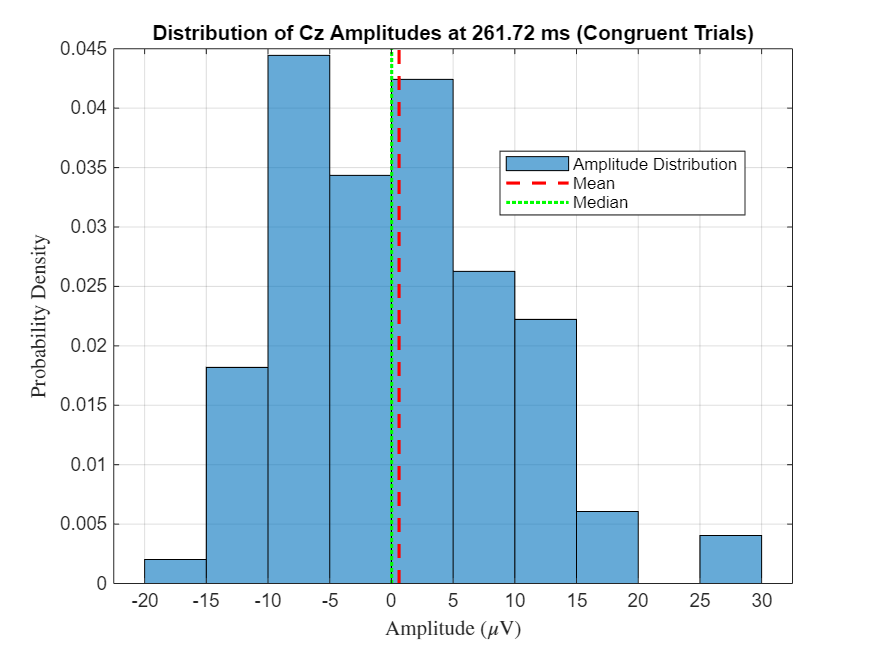

% What it gives: Whether the distribution has heavy tails (more outliers) and a sharp peak (leptokurtic, kurtosis > 0) or light tails and a flat peak (platykurtic, kurtosis < 0) compared to a normal distribution (kurtosis = 0).
% What it doesn't give: The symmetry or the central tendency.

% Histogram: Visual representation of data frequency distribution.
figure('Name', 'Distribution of ERP Amplitudes at N200 Peak');
histogram(amplitudes_at_peak, 'Normalization', 'pdf'); % Normalized to show probability density
hold on;
% Plot mean and median for reference
plot([erp_mean erp_mean], ylim, 'r--', 'LineWidth', 1.5);
plot([erp_median erp_median], ylim, 'g:', 'LineWidth', 1.5);
legend('Amplitude Distribution', 'Mean', 'Median', 'Location', 'best');
title(sprintf('Distribution of Cz Amplitudes at %.2f ms (Congruent Trials)', peak_time_ms));
% Key change here: using 'Interpreter', 'latex' for proper micro symbol display
xlabel('Amplitude ($\mu$V)', 'Interpreter', 'latex');
ylabel('Probability Density', 'Interpreter', 'latex');
grid on;
hold off;



fprintf('\n--- End of Descriptive Statistics Analysis ---\n');


--- End of Descriptive Statistics Analysis ---


## **Outlier Detection**:

- **Why Outliers are a Problem**: Can heavily bias means, standard deviations, and statistical test results.

- **Basic Identification Methods**:

- Visual inspection (histograms, box plots).

- Statistical criteria (e.g., values beyond ±3 SD from the mean, or 1.5×IQR rule).

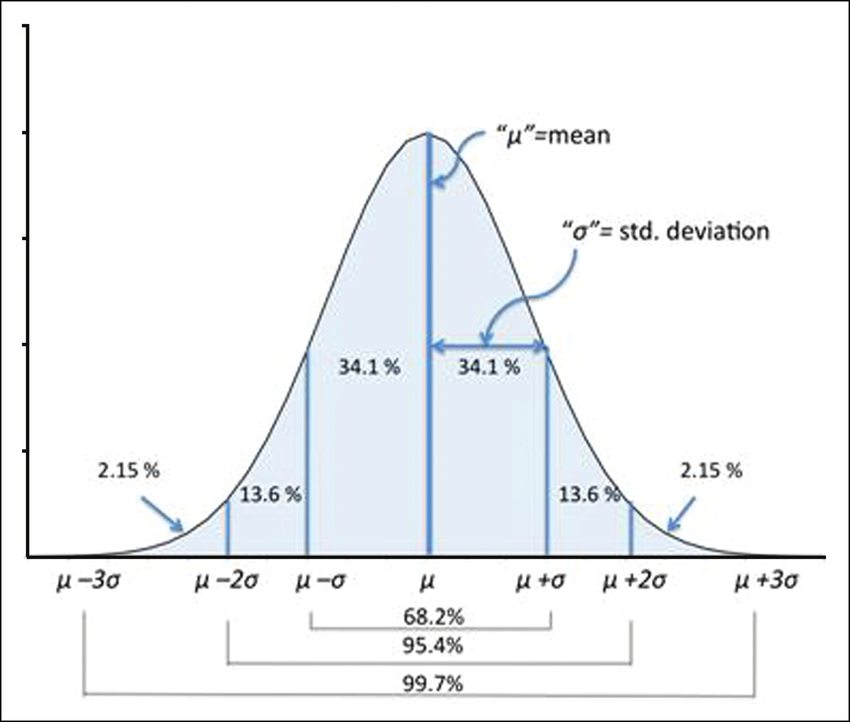

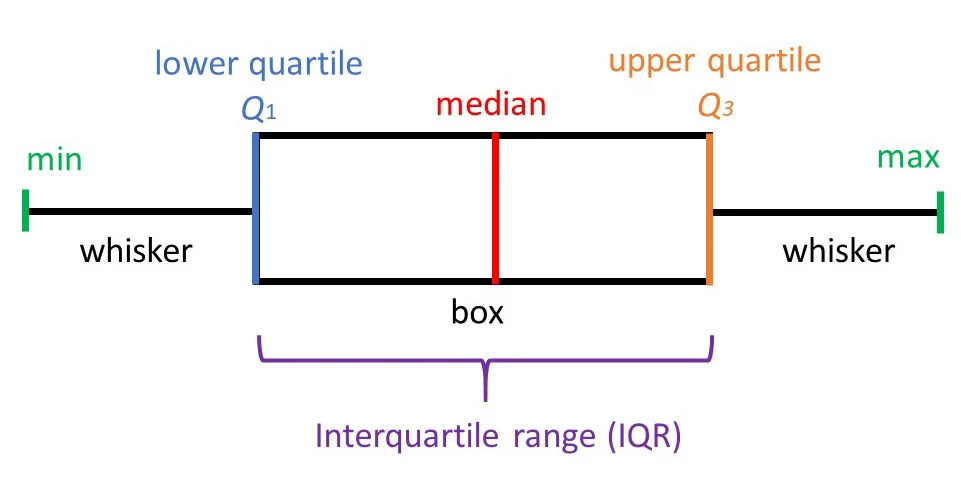

% --- Outlier Detection on Cohen & Ridderinkhof Data ---

% IMPORTANT: Ensure EEGLAB is installed and added to your MATLAB path.
% Run 'eeglab' in the command window once to initialize.


% Define event code and channel for analysis.
congruent_event_code = 1;
cz_channel_index = 48; % Cz channel is commonly the 48th electrode

fprintf('--- Starting Outlier Detection for Congruent ERP (Cz) ---\n');

--- Starting Outlier Detection for Congruent ERP (Cz) ---



% --- 1. Separate Trials for Congruent Condition ---
fprintf('Separating trials for Congruent condition (event code %d)...\n', congruent_event_code);

Separating trials for Congruent condition (event code 1)...


EEG_congruent = pop_selectevent(EEG, 'type', congruent_event_code, 'deleteevents', 'on');

% --- 2. Preprocessing: Filter Data ---
fprintf('Applying high-pass (0.5 Hz) and low-pass (30 Hz) filters...\n');

Applying high-pass (0.5 Hz) and low-pass (30 Hz) filters...


EEG_congruent = pop_eegfiltnew(EEG_congruent, 'locutoff', 0.5, 'hicutoff', 30);

pop_eegfiltnew() - performing 1691 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.499881656804734 Hz
pop_eegfiltnew() - passband edge(s): [0.5 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.250059171597633 30.2499408284024] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


% --- 3. Extract Amplitudes at a Specific Time Point ---
% We'll analyze the amplitude distribution at the N200 peak.
cz_congruent_data = squeeze(EEG_congruent.data(cz_channel_index, :, :));
mean_erp_congruent = mean(cz_congruent_data, 2);

% Define a time window for the N200 peak (e.g., 200-400 ms post-stimulus).
time_window_start = 200; % ms
time_window_end = 400;   % ms

% Convert time window to indices.
[~, start_idx] = min(abs(EEG_congruent.times - time_window_start));
[~, end_idx] = min(abs(EEG_congruent.times - time_window_end));

% Find the most negative peak (N200-like) within this window.
[~, relative_peak_idx] = min(mean_erp_congruent(start_idx:end_idx));
peak_time_idx = start_idx + relative_peak_idx - 1; % Absolute index of the peak
peak_time_ms = EEG_congruent.times(peak_time_idx);

fprintf('\nAnalyzing ERP amplitudes at the identified N200 peak (%.2f ms) across trials.\n', peak_time_ms);


Analyzing ERP amplitudes at the identified N200 peak (261.72 ms) across trials.



% Extract the amplitude values from each trial at this specific peak time.
amplitudes_at_peak = cz_congruent_data(peak_time_idx, :);
amplitudes_at_peak = amplitudes_at_peak(:); % Ensure it's a column vector for some functions

% --- 4. Outlier Identification Methods ---

fprintf('\n--- Outlier Detection Results ---\n');


--- Outlier Detection Results ---



% Calculate descriptive statistics needed for outlier detection
data_mean = mean(amplitudes_at_peak);
data_std = std(amplitudes_at_peak);
data_q1 = prctile(amplitudes_at_peak, 25);
data_q3 = prctile(amplitudes_at_peak, 75);
data_iqr = data_q3 - data_q1;

% Method 1: Standard Deviation Rule (e.g., beyond \xB13 SD from the mean)
% This method assumes a roughly normal distribution.
std_threshold = 3; % Common threshold for SD rule
lower_sd_bound = data_mean - std_threshold * data_std;
upper_sd_bound = data_mean + std_threshold * data_std;

outliers_sd_idx = (amplitudes_at_peak < lower_sd_bound) | (amplitudes_at_peak > upper_sd_bound);
num_outliers_sd = sum(outliers_sd_idx);

fprintf('Standard Deviation Rule (+/-%.0f SD from mean):\n', std_threshold); % Changed to +/-

Standard Deviation Rule (+/-3 SD from mean):


fprintf('  Lower Bound: %.2f uV, Upper Bound: %.2f uV\n', lower_sd_bound, upper_sd_bound);

  Lower Bound: -26.63 uV, Upper Bound: 27.86 uV


fprintf('  Number of outliers detected: %d\n', num_outliers_sd);

  Number of outliers detected: 1


if num_outliers_sd > 0
    fprintf('  Outlier amplitudes: %s uV\n', mat2str(amplitudes_at_peak(outliers_sd_idx)'));
end

  Outlier amplitudes: 28.5927467346191 uV



% Method 2: IQR Rule (1.5 * IQR rule / Tukey's Fences)
% This method is more robust to skewed distributions and outliers.
iqr_factor = 1.5; % Common threshold for IQR rule
lower_iqr_bound = data_q1 - iqr_factor * data_iqr;
upper_iqr_bound = data_q3 + iqr_factor * data_iqr;

outliers_iqr_idx = (amplitudes_at_peak < lower_iqr_bound) | (amplitudes_at_peak > upper_iqr_bound);
num_outliers_iqr = sum(outliers_iqr_idx);

fprintf('\nIQR Rule (%.1f x IQR from Q1/Q3):\n', iqr_factor);


IQR Rule (1.5 x IQR from Q1/Q3):


fprintf('  Lower Bound: %.2f uV, Upper Bound: %.2f uV\n', lower_iqr_bound, upper_iqr_bound);

  Lower Bound: -26.42 uV, Upper Bound: 25.78 uV


fprintf('  Number of outliers detected: %d\n', num_outliers_iqr);

  Number of outliers detected: 2


if num_outliers_iqr > 0
    fprintf('  Outlier amplitudes: %s uV\n', mat2str(amplitudes_at_peak(outliers_iqr_idx)'));
end

  Outlier amplitudes: [27.2710762023926;28.5927467346191] uV


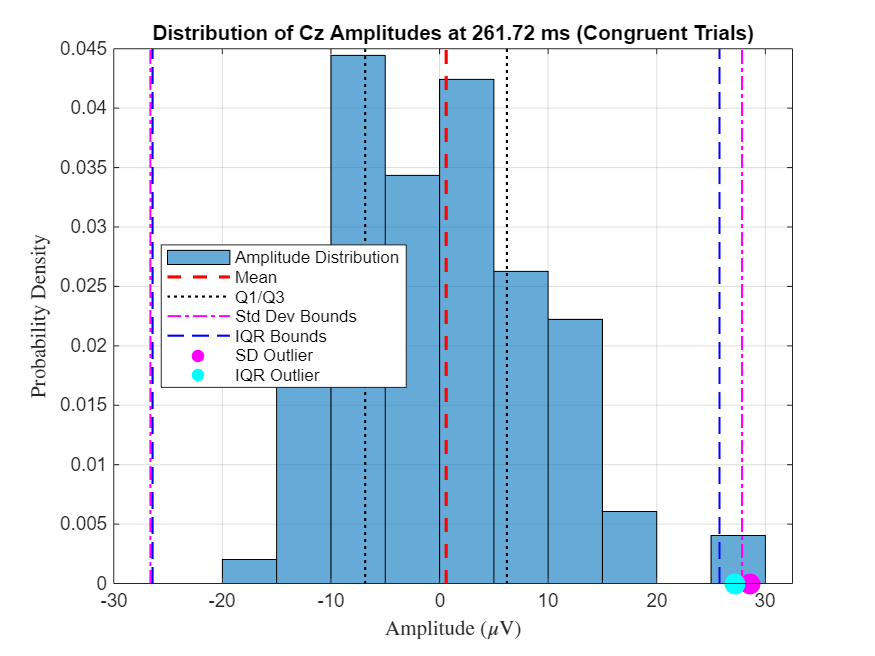

% --- 5. Visual Inspection Methods ---

% Visual Inspection 1: Histogram
figure('Name', 'Distribution of ERP Amplitudes with Outlier Bounds');

% Initialize arrays for plot handles and legend labels
plot_handles = [];
legend_labels = {};

% Histogram itself
h_hist = histogram(amplitudes_at_peak, 'Normalization', 'pdf');
plot_handles = [plot_handles, h_hist];
legend_labels = [legend_labels, 'Amplitude Distribution'];

hold on;

% Mean line
h_mean = plot([data_mean data_mean], ylim, 'r--', 'LineWidth', 1.5);
plot_handles = [plot_handles, h_mean];
legend_labels = [legend_labels, 'Mean'];

% Q1/Q3 lines (plot both, add only one handle to represent them in the legend)
h_q1 = plot([data_q1 data_q1], ylim, 'k:', 'LineWidth', 1);
plot([data_q3 data_q3], ylim, 'k:', 'LineWidth', 1); % This line won't get a separate legend entry
plot_handles = [plot_handles, h_q1];
legend_labels = [legend_labels, 'Q1/Q3'];

% SD bounds lines (plot both, add only one handle)
h_sd_lower = plot([lower_sd_bound lower_sd_bound], ylim, 'm-.', 'LineWidth', 1);
plot([upper_sd_bound upper_sd_bound], ylim, 'm-.', 'LineWidth', 1); % This line won't get a separate legend entry
plot_handles = [plot_handles, h_sd_lower];
legend_labels = [legend_labels, 'Std Dev Bounds'];

% IQR bounds lines (plot both, add only one handle) - Changed to 'b--' for clarity based on user feedback
h_iqr_lower = plot([lower_iqr_bound lower_iqr_bound], ylim, 'b--', 'LineWidth', 1);
plot([upper_iqr_bound upper_iqr_bound], ylim, 'b--', 'LineWidth', 1); % This line won't get a separate legend entry
plot_handles = [plot_handles, h_iqr_lower];
legend_labels = [legend_labels, 'IQR Bounds'];

% Highlight outliers on the histogram if any
% Outliers identified by SD rule
if num_outliers_sd > 0
    % Corrected scatter syntax: specify color and 'filled' separately as recognized options
    h_outliers_sd = scatter(amplitudes_at_peak(outliers_sd_idx), zeros(num_outliers_sd,1), 100, 'm', 'filled', 'Marker', 'o', 'Clipping', 'off');
    plot_handles = [plot_handles, h_outliers_sd];
    legend_labels = [legend_labels, 'SD Outlier'];
end
% Outliers identified by IQR rule but not by SD rule (to differentiate)
iqr_only_outliers_idx = outliers_iqr_idx & ~outliers_sd_idx;
if sum(iqr_only_outliers_idx) > 0
    % Corrected scatter syntax: specify color and 'filled' separately as recognized options
    h_outliers_iqr = scatter(amplitudes_at_peak(iqr_only_outliers_idx), zeros(sum(iqr_only_outliers_idx),1), 100, 'c', 'filled', 'Marker', 'o', 'Clipping', 'off');
    plot_handles = [plot_handles, h_outliers_iqr];
    legend_labels = [legend_labels, 'IQR Outlier'];
end


% Apply the legend to all collected handles
legend(plot_handles, legend_labels, 'Location', 'best');

title(sprintf('Distribution of Cz Amplitudes at %.2f ms (Congruent Trials)', peak_time_ms));
xlabel('Amplitude ($\mu$V)', 'Interpreter', 'latex');
ylabel('Probability Density', 'Interpreter', 'latex');
grid on;
hold off;

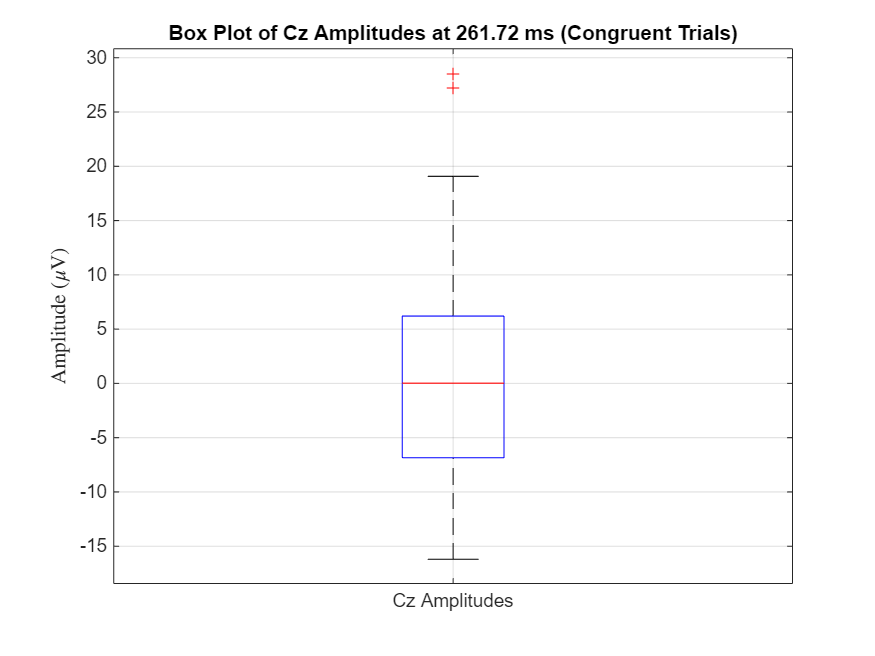


% Visual Inspection 2: Box Plot
figure('Name', 'Box Plot of ERP Amplitudes with Outliers');
boxplot(amplitudes_at_peak, 'Labels', {'Cz Amplitudes'});
title(sprintf('Box Plot of Cz Amplitudes at %.2f ms (Congruent Trials)', peak_time_ms));
ylabel('Amplitude ($\mu$V)', 'Interpreter', 'latex');
grid on;


fprintf('\n--- End of Outlier Detection Analysis ---\n');


--- End of Outlier Detection Analysis ---
